# (3) 1-Class SVMによる異常検知

## はじめに

これまでの2手法 (ホテリングの$T^2$法と混合分布モデル) は、いずれもデータの分布としてガウス分布を仮定したものでした。しかしながら実際のデータ分布は、分布に片寄りがあるなど、しばしばガウス分布で近似できないようなケースが見られます。このような場合には、1-Class SVMによる異常検知が適しています。

以下では、これまでと同様に発生頻度が5%, 1% および 0.1%の異常を検出するために、どのように1-Class SVMを適用すれば良いのかを見ていきましょう。

## 前処理済みのデータの読み込み

あらかじめ作成した前処理済みのデータを読み込みます。

load('Preprocessed_FD001.mat');

## 1-Class SVMによる異常検知

簡単のため、以下では第1主成分-第2主成分平面上でのデータ分布に対して、混合分布モデルを構築します。

まず、'long' とラベル付けされたデータを「正常データ」と想定して、正常データ群の分布に沿った曲面を 1-Class SVM で計算します。

次に、異常を判別するための閾値として、発生頻度が 5%, 1% および 0.1% を想定し、上記で構築した1-Class SVMモデルからそれぞれに対応する閾値を求めます。

最後に、主成分平面上でのデータ点の分布と、発生頻度 5%, 1% および 0.1% の異常を判別するための境界線を図示します。

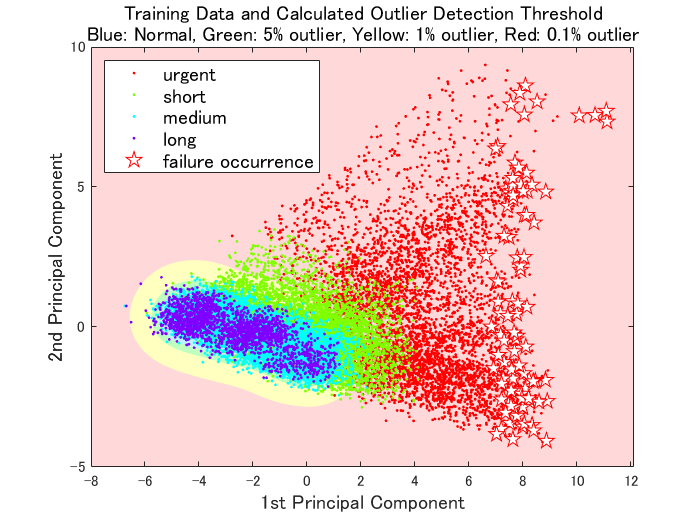

% 発生頻度が 5%, 1% および 0.1% の異常を検出するための閾値を求めるための準備
idx = (dataTrainZ.Label == 'long');
th = [0.001, 0.01, 0.05];
mdlSVM = cell(3,1);
C = cell(3,1);

d = 0.1;
[x1Grid, x2Grid] = meshgrid(-8:d:8, -8:d:8);
for kk = 1:3
    mdlSVM{kk} = fitcsvm(score(idx,1:2), ones(nnz(idx),1),...
        'KernelFunction',   'rbf',...
        'OutlierFraction',  th(kk));
    [~, aGrid] = predict(mdlSVM{kk}, [x1Grid(:) x2Grid(:)]);
    aGrid = reshape(aGrid, size(x1Grid,1), size(x2Grid,2));
    
    % 1-Class SVMに基づく閾値を算出
    C{kk} = contourc((-8:d:8), (-8:d:8), aGrid, [0 0]);
end

% 発生頻度 5%, 1% および 0.1% に対応する色を設定
col5per = [0.75 0.95 1];
col1per = [0.75 1 0.75];
col01per = [1 1 0.75];
colAnomaly = [1 0.85 0.85];

% 結果を可視化
figure
plotContourmatrix(C{1}, col01per);
plotContourmatrix(C{2}, col1per);
plotContourmatrix(C{3}, col5per);
hold on;
s1 = gscatter(score(:,1),...
    score(:,2),...
    dataTrainZ.Label);
idx = dataTrainZ.Time == 0;
s2 = plot(score(idx,1),...
    score(idx,2),'rp','MarkerSize',10,'MarkerFaceColor','w');
legend([s1; s2],{'urgent','short','medium','long','failure occurrence'},...
    'Color',    [1 1 1],...
    'Location', 'northwest',...
    'FontSize', 12);
ax = gca;
ax.Color = colAnomaly;
ax.Box = 'on';
xlabel('1st Principal Component','FontSize',12);
ylabel('2nd Principal Component','FontSize',12);
title({'Training Data and Calculated Outlier Detection Threshold';...
    'Blue: Normal, Green: 5% outlier, Yellow: 1% outlier, Red: 0.1% outlier'},'FontSize',12)

## 検証用データによる確認

最後に、ホテリングの$T^2$法のデモと同様に、学習用データをもとに算出した閾値を、検証用データに対して適用してみます。その結果、検証用データで 'urgent' とラベル付けされたデータを検出するには、1% 用の閾値を用いると良いということが確認できました。

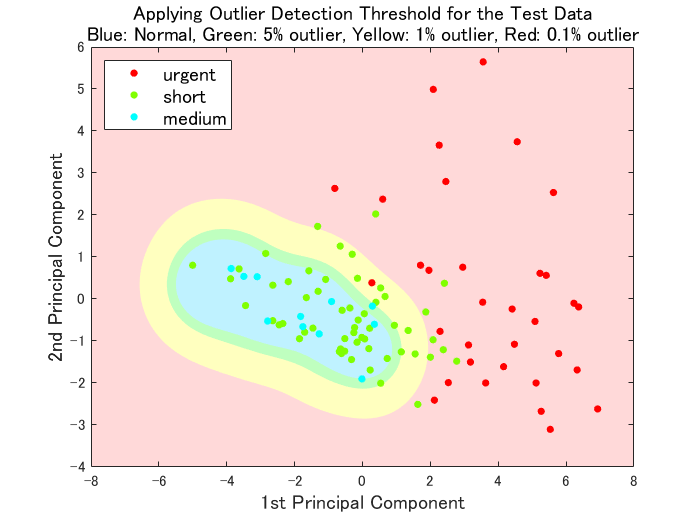

% 検証用データの標準化
dataTestZ = dataTest;
dataTestZ{:,3:end-1} = (dataTest{:,3:end-1} - mu)./sigma;

score = dataTestZ{:,3:end-1}*wcoeff;

% 結果を可視化
figure
plotContourmatrix(C{1}, col01per);
plotContourmatrix(C{2}, col1per);
plotContourmatrix(C{3}, col5per);
hold on;
s1 = gscatter(score(:,1),...
    score(:,2),...
    dataTestZ.Label);
legend(s1,{s1.DisplayName},...
    'Color',    [1 1 1],...
    'Location', 'northwest',...
    'FontSize', 12);
ax = gca;
ax.Color = colAnomaly;
ax.Box = 'on';
xlabel('1st Principal Component','FontSize',12);
ylabel('2nd Principal Component','FontSize',12);
title({'Applying Outlier Detection Threshold for the Test Data';...
    'Blue: Normal, Green: 5% outlier, Yellow: 1% outlier, Red: 0.1% outlier'},'FontSize',12)

*Copyright 2020 The MathWorks, Inc.*